# Analyzing Satellite Images of a Flood

Included in the course files are two satellite images of the Mississippi River, one taken before a flood and one taken after. You can determine the increase in area covered with water using the image processing techniques you've learned so far.

### Import and display the images

First, import and examine both images.

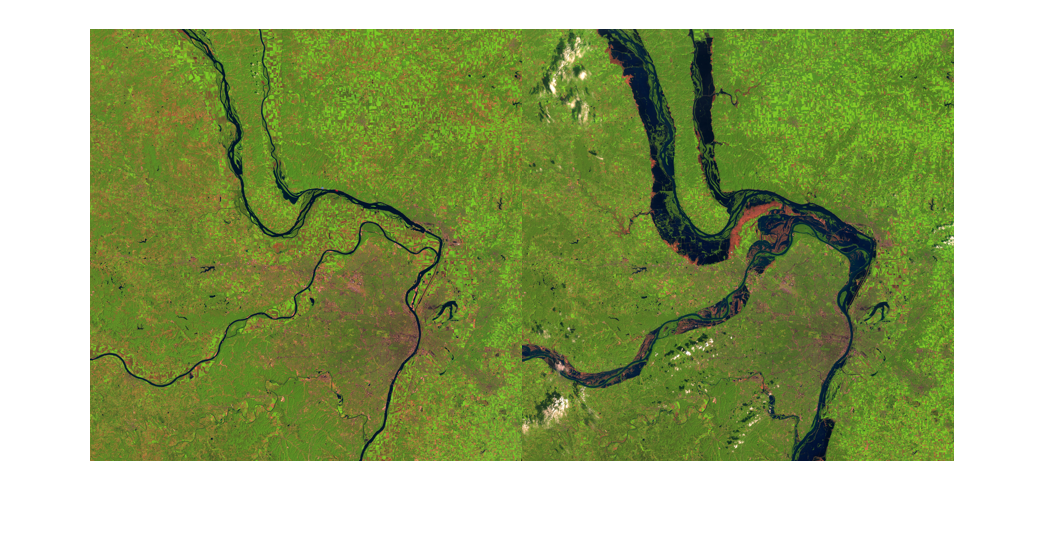

preflood = imread("stlouis_l5tm_14aug91_30m.jpg");
postflood = imread("stlouis_l5tm_19aug93_30m.jpg");
montage({preflood,postflood})

You can immediately see the amount of water changed a lot, but by how much? 

### Color thresholding

Go to the Color Thresholding App and import the preflood image. Try to segment out the dark blue river areas. 

After you are satisfied with your segmentation in the app, export the function and check that it works on the other image. If the mask doesn't look how you expected, go back and refine your segmentation function. If you get stuck, see the hint at the bottom of this script.

Insert your segmentation function below with the preflood image as input and uncomment the lines. Use the provided variable names since they will be used in the rest of the script.

[BWpre, maskpre] = RiverMaskHSV(preflood)

BWpre = 3600×3600 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

maskpre = 3600×3600×3 uint8 array
maskpre(:,:,1) =

  Columns 1 through 1 999

    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0 

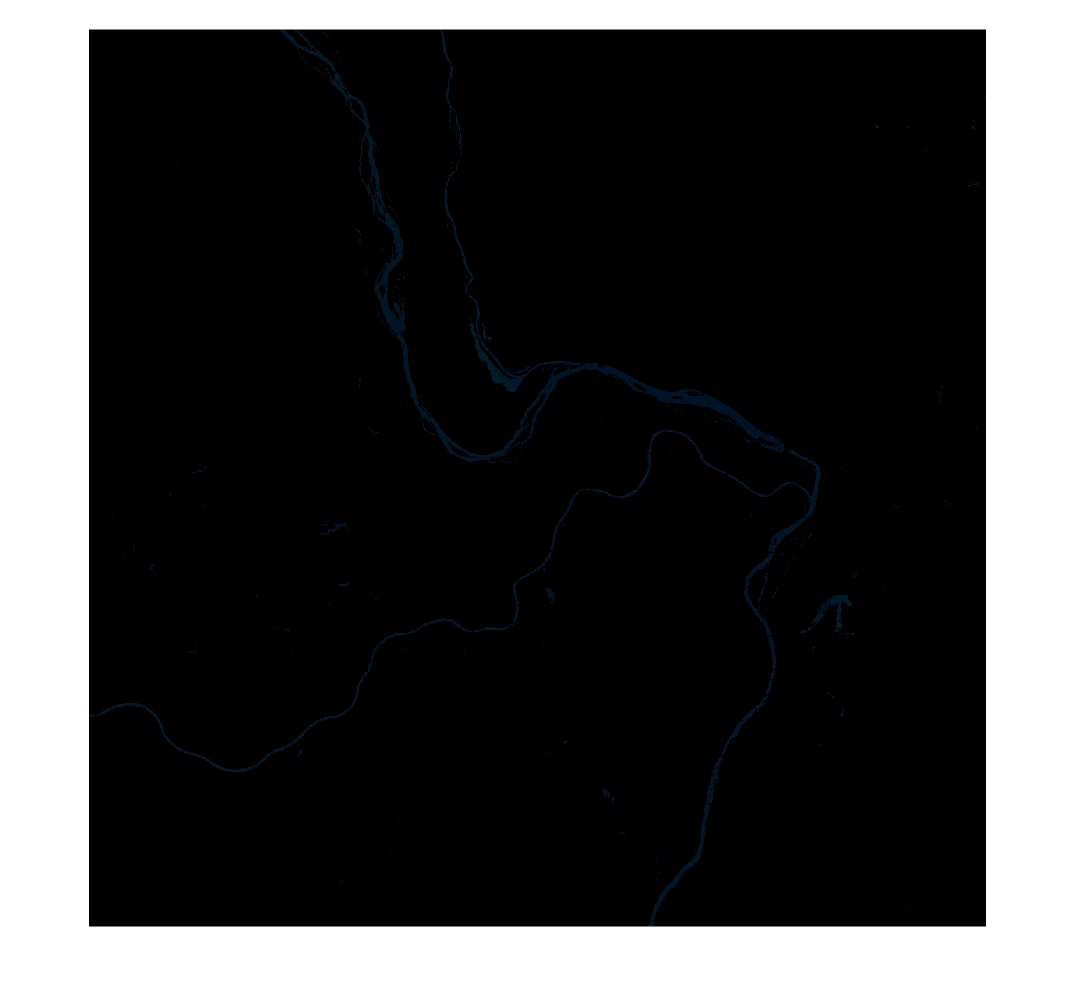

imshow(maskpre)

Now do the same thing for the postflood image.

[BWpost, maskpost] = RiverMaskHSV(postflood)

BWpost = 3600×3600 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

maskpost = 3600×3600×3 uint8 array
maskpost(:,:,1) =

  Columns 1 through 1 999

    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    

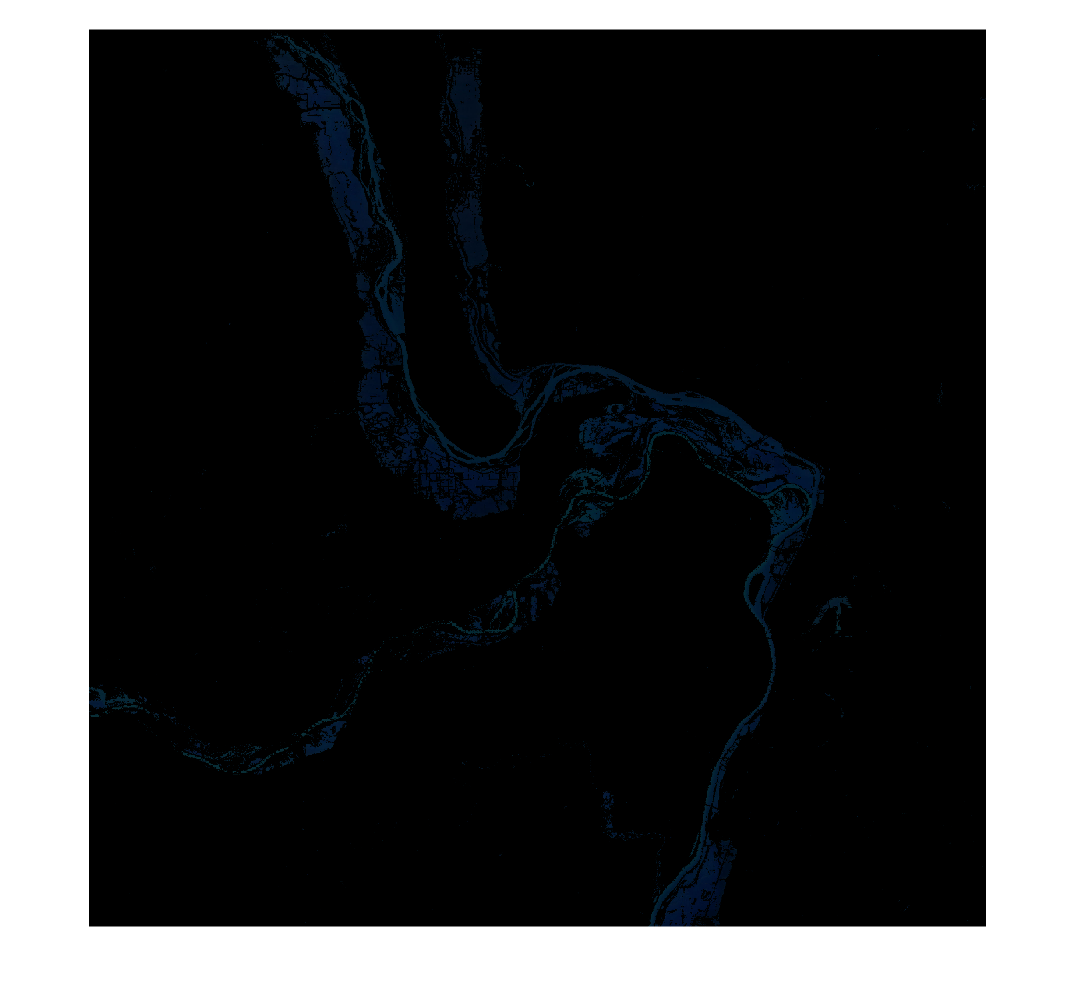

imshow(maskpost)

### Numerical analysis

Use the segmentation function outputs and the `nnz` function to calculate the number of blue river pixels in each image. Let's take a look at the results. 

nnz(BWpre)

ans = 218632

nnz(BWpost)

ans = 706764

Your results for the preflood image should be between 250,000 and 290,000, and your results for the postflood image should be between 1,000,000 and 1,100,000. If your results do not fall within this range, you should try going back and further refining your segmentation function.

Finally, calculate the increase in pixel values between the first and second images.

(nnz(BWpost) - nnz(BWpre)) / nnz(BWpre) * 100

ans = 223.2665

You should be seeing a value of around 277%. That's a huge increase in water area due to the flood! 

### Hint for segmenting the images

*Spoiler Alert*! Try segmenting the images yourself first, but if you get stuck, use the screenshot below to help you find an appropiate threshold.

coins = imread("coins_module3.jpg")

coins = 2448×3264 uint8 matrix
   122   123   122   117   111   111   115   120   110   111   115   120   116   108   106   111   110   117   117   112   113   117   110    97   103   110   118   121   120   116   113   112   118   119   119   118   116   116   119   121   125   124   122   120   118   116   114   113   115   116
   122   121   117   111   105   104   107   111   110   110   113   116   112   106   108   113   114   119   118   111   113   119   116   106   104   109   116   119   117   114   112   112   111   112   113   113   113   116   120   124   125   124   122   120   119   118   117   117   116   116
   116   115   112   108   104   103   105   108   110   110   111   112   109   105   108   114   120   122   119   112   113   120   121   115   106   110   114   115   115   113   112   112   106   107   109   111   113   116   121   125   121   120   118   117   117   117   119   119   116   116
   105   106   108   110   112   112   112   111   109   111   113

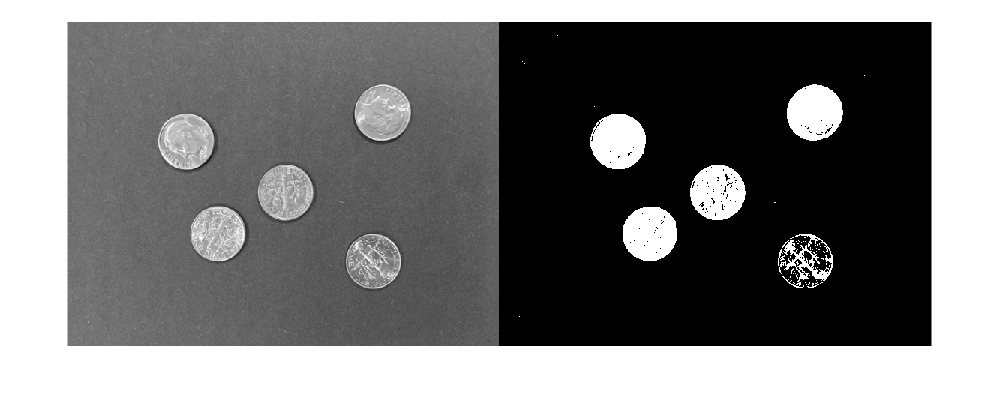

ans = 0.5608

BW1 = imbinarize(coins);
montage({coins, BW1})

graythresh(coins) * 255

ans = 143

nnz(BW1)

ans = 594617

[~,effectivenessMetric_c] = graythresh(coins)

effectivenessMetric_c = 0.6967

BW2 = imbinarize(coins,"adaptive")

BW2 = 2448×3264 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

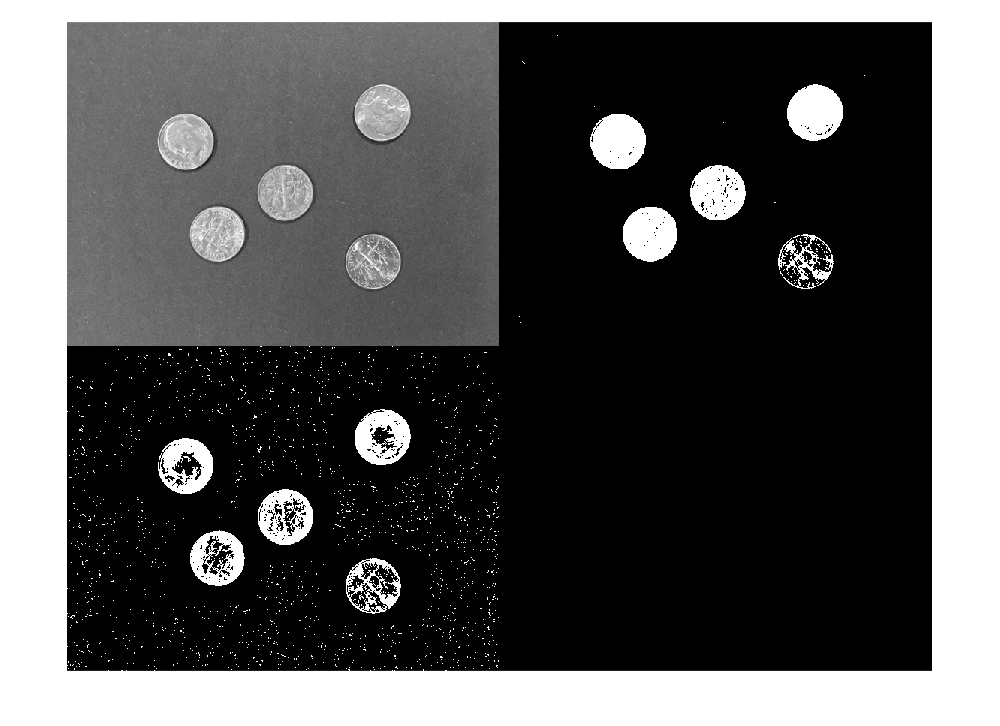

montage({coins, BW1,BW2})

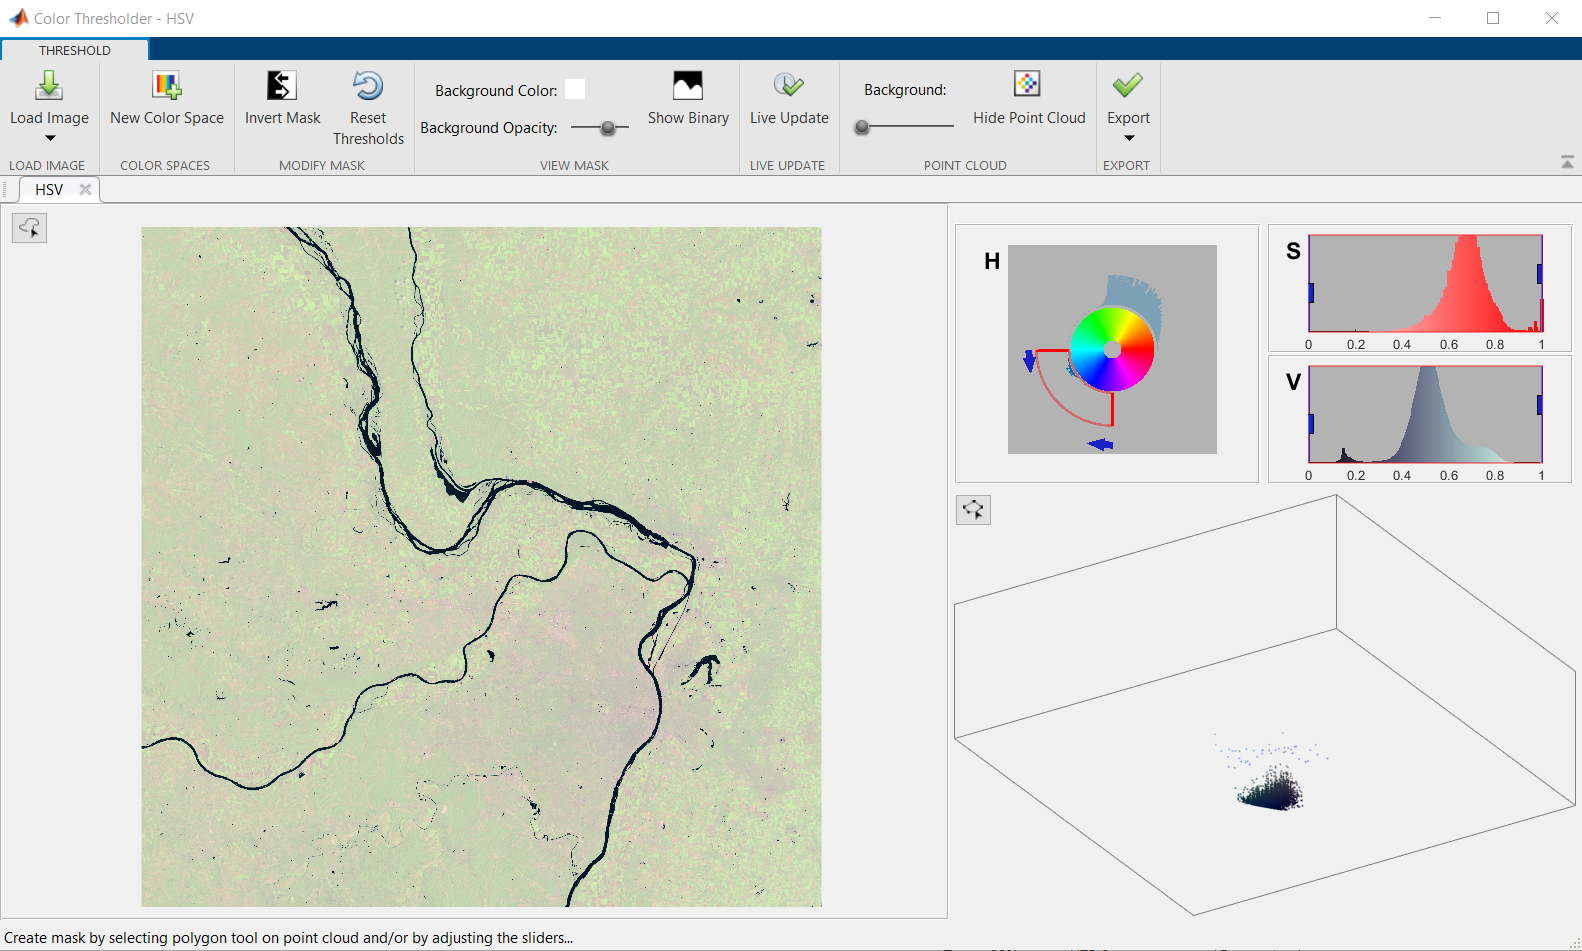

*Copyright 2022 The MathWorks, Inc.*